LL = -5

LL = -5

UL = 80

UL = 80

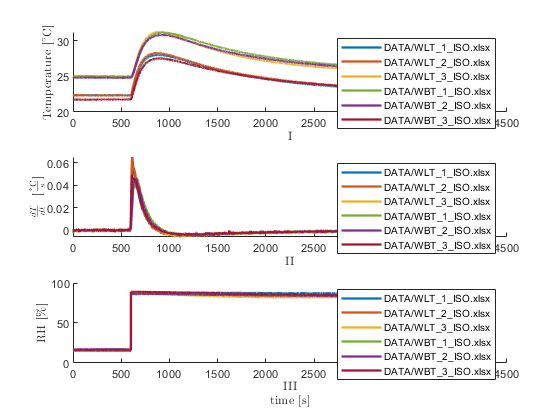

WT_ISO = ISO_Material({'DATA/WLT_1_ISO.xlsx', 'DATA/WLT_2_ISO.xlsx', 'DATA/WLT_3_ISO.xlsx', 'DATA/WBT_1_ISO.xlsx', 'DATA/WBT_2_ISO.xlsx', 'DATA/WBT_3_ISO.xlsx'});
% Type ,Square_Length_mm, thickness_mm, Weight_Density, cp_fabric, R_cf
% THICK
WT_ISO.Material_Data('Wool-Thick', 50, 0.6517, 217.05, 1559.4179, 0.155)
% WT_ISO.Plot_Smoothing_Delta_T
WT_ISO.Plot_Raw_Data

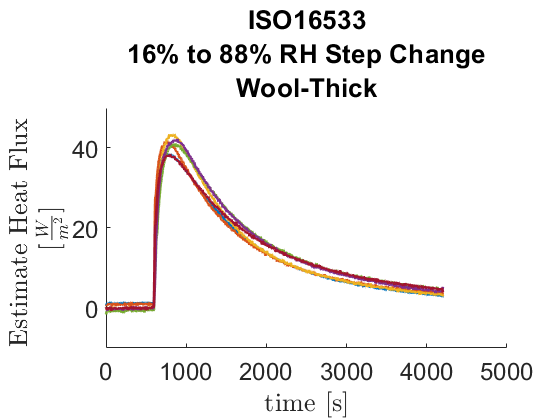

WT_ISO.Calculate_Flux
WT_ISO.Plot_Flux

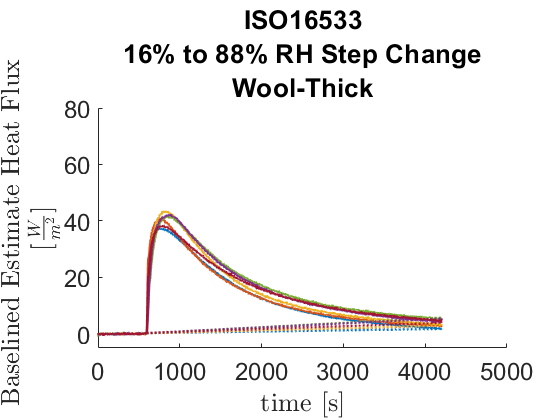

WT_ISO.Create_Basline(1, [])
WT_ISO.Impose_Temp
WT_ISO.Plot_Baseline([0 5000], [LL UL])

WT_ISO.Calculate_Theoretical_Energy(8.34, 15, 85)
WT_ISO.Compile_Results


% create method for integrating baseline values

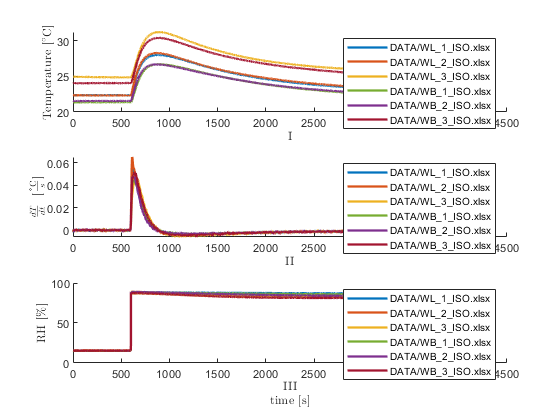

W_ISO = ISO_Material({'DATA/WL_1_ISO.xlsx', 'DATA/WL_2_ISO.xlsx', 'DATA/WL_3_ISO.xlsx', 'DATA/WB_1_ISO.xlsx', 'DATA/WB_2_ISO.xlsx', 'DATA/WB_3_ISO.xlsx'});
% Type ,Square_Length_mm, thickness_mm, Weight_Density, cp_fabric, R_cf
% THIN
W_ISO.Material_Data('Wool-Thin', 50, 0.4350, 185.3481, 1559.4179, 0.0945)
% W_ISO.Plot_Smoothing_Delta_T
W_ISO.Plot_Raw_Data

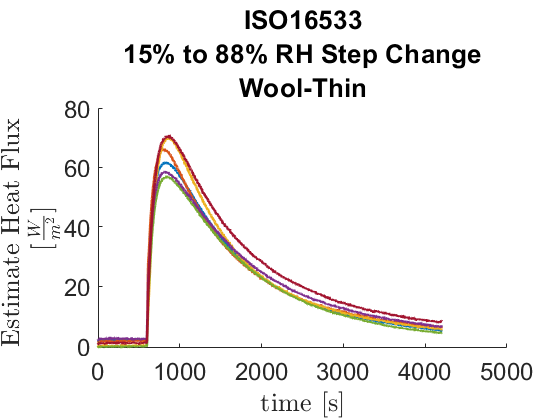

W_ISO.Calculate_Flux
W_ISO.Plot_Flux

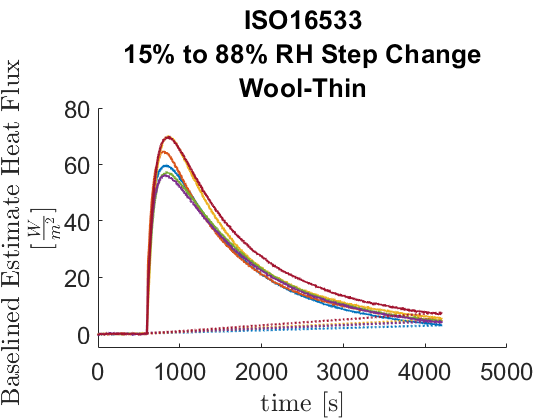

W_ISO.Create_Basline(1, [])
W_ISO.Impose_Temp
W_ISO.Plot_Baseline([0 5000], [LL UL])

W_ISO.Calculate_Theoretical_Energy(8.27, 15, 85)
W_ISO.Compile_Results

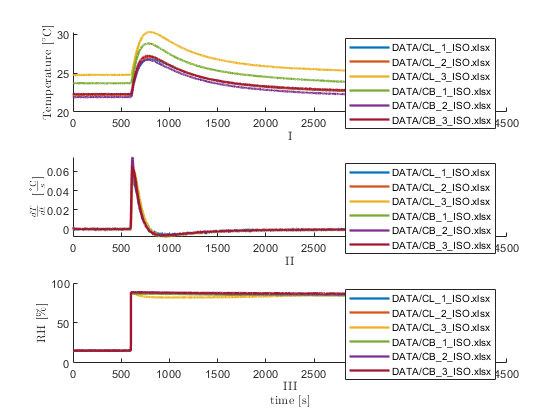

C_ISO = ISO_Material({'DATA/CL_1_ISO.xlsx', 'DATA/CL_2_ISO.xlsx', 'DATA/CL_3_ISO.xlsx', 'DATA/CB_1_ISO.xlsx', 'DATA/CB_2_ISO.xlsx', 'DATA/CB_3_ISO.xlsx'});
C_ISO.Material_Data('Cotton-Thin', 50, 0.493, 184.21, 1559.4179, 0.0995)
% C_ISO.Plot_Smoothing_Delta_T
C_ISO.Plot_Raw_Data

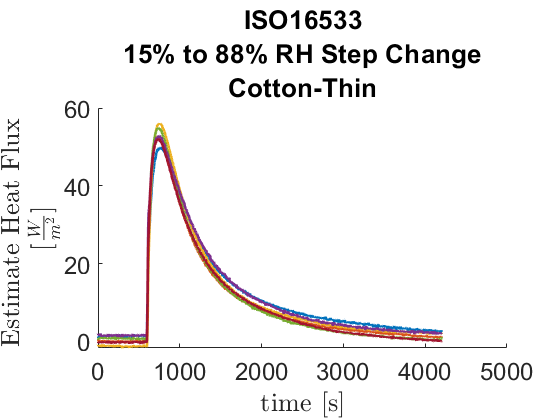

C_ISO.Calculate_Flux
C_ISO.Plot_Flux

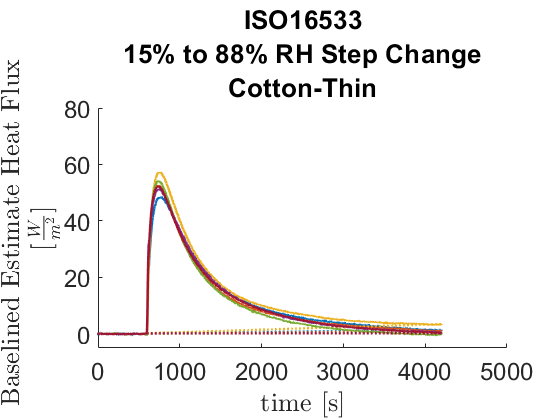

C_ISO.Create_Basline(1, [])
C_ISO.Impose_Temp
C_ISO.Plot_Baseline([0 5000], [LL UL])

C_ISO.Calculate_Theoretical_Energy(7.32, 15, 85)
C_ISO.Compile_Results

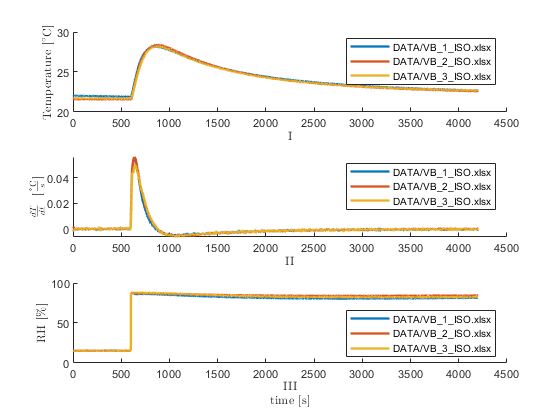

V_ISO = ISO_Material({'DATA/VB_1_ISO.xlsx', 'DATA/VB_2_ISO.xlsx', 'DATA/VB_3_ISO.xlsx'});
V_ISO.Material_Data('Viscose-Thin', 50, 0.477, 240.25, 1559.4179, 0.095)
% V_ISO.Plot_Smoothing_Delta_T
V_ISO.Plot_Raw_Data

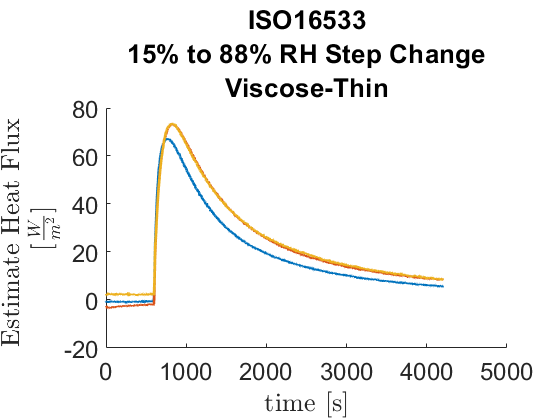

V_ISO.Calculate_Flux
V_ISO.Plot_Flux

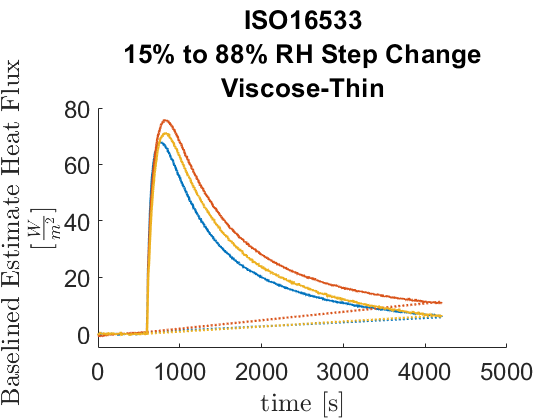

V_ISO.Create_Basline(1, [])
V_ISO.Impose_Temp
V_ISO.Plot_Baseline([0 5000], [LL UL])

V_ISO.Calculate_Theoretical_Energy(14.57, 15, 85)
V_ISO.Compile_Results

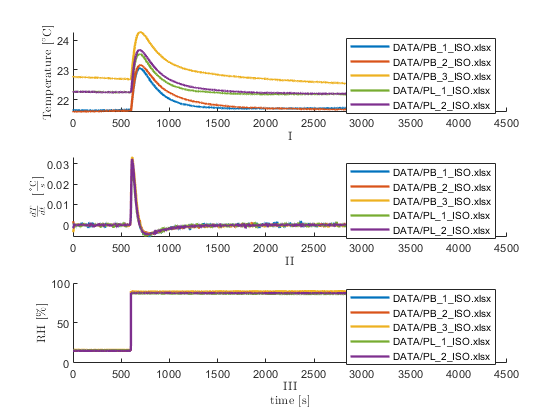

P_ISO = ISO_Material({'DATA/PB_1_ISO.xlsx', 'DATA/PB_2_ISO.xlsx', 'DATA/PB_3_ISO.xlsx' ,'DATA/PL_1_ISO.xlsx', 'DATA/PL_2_ISO.xlsx'});
% P_ISO.Material_Data('Polyester-Thin', 50, 0.45, 175.0, 1559.4179, 0.005)
P_ISO.Material_Data('Polyester-Thin', 50, 0.45, 212.24, 1559.4179, 0.0805)
% P_ISO.Plot_Smoothing_Delta_T
P_ISO.Plot_Raw_Data

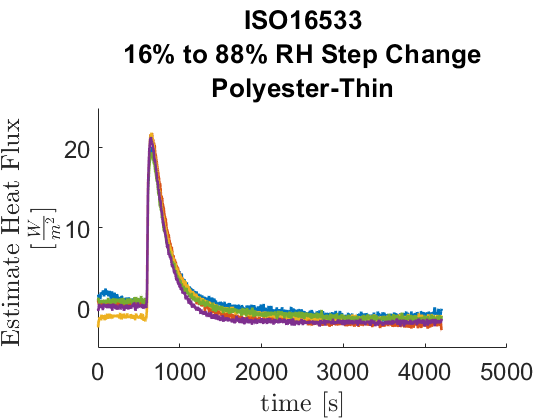

P_ISO.Calculate_Flux
P_ISO.Plot_Flux

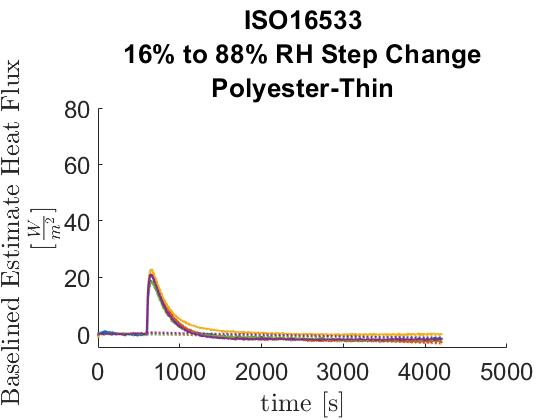

P_ISO.Create_Basline(1, [])
P_ISO.Impose_Temp() 
P_ISO.Plot_Baseline([0 5000], [LL UL])

P_ISO.Calculate_Theoretical_Energy(0.66, 15, 85)
P_ISO.Compile_Results

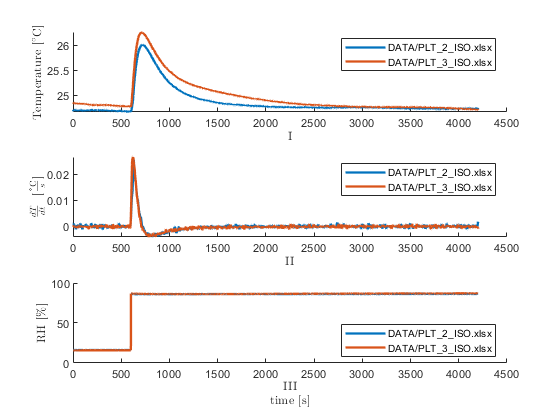

% PT_ISO = ISO_Material({'DATA/PLT_1_ISO.xlsx', 'DATA/PLT_2_ISO.xlsx', 'DATA/PLT_3_ISO.xlsx'});
PT_ISO = ISO_Material({'DATA/PLT_2_ISO.xlsx', 'DATA/PLT_3_ISO.xlsx'});
PT_ISO.Material_Data('Polyester-Thick', 50, 0.69, 198.296, 1559.4179, 0.0820)
% PT_ISO.Plot_Smoothing_Delta_T
PT_ISO.Plot_Raw_Data

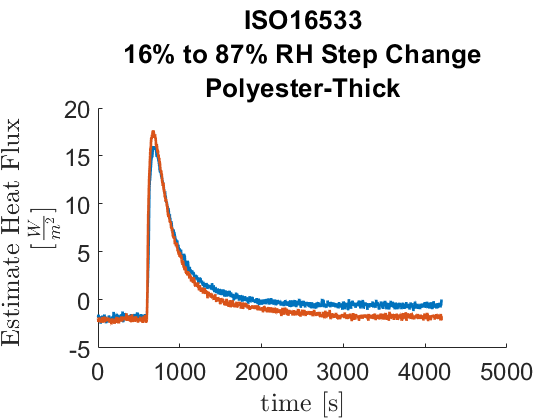

PT_ISO.Calculate_Flux
PT_ISO.Plot_Flux

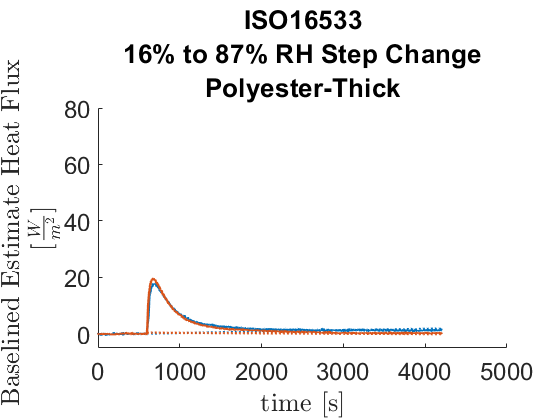

PT_ISO.Create_Basline(1, [])
PT_ISO.Impose_Temp()
PT_ISO.Plot_Baseline([0 5000], [LL UL])

PT_ISO.Calculate_Theoretical_Energy(0.62, 15, 85)
PT_ISO.Compile_Results

ISO_Material.export_results

Exported: Integrated_Flux_Energy_Normalized_ISO_METHOD.csv
Exported: Integrated_Flux_Energy_Total_ISO_METHOD.csv
Exported: Integrated_Flux_Energy_Theory_ISO_METHOD.csv


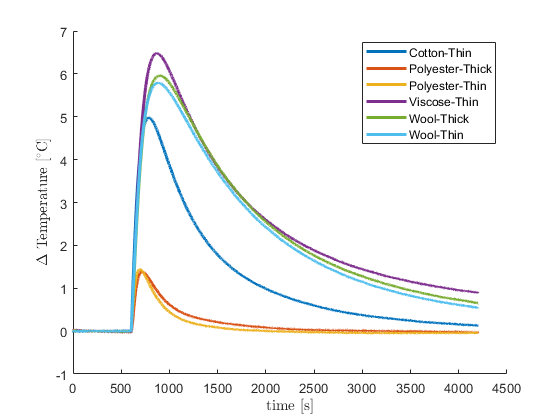

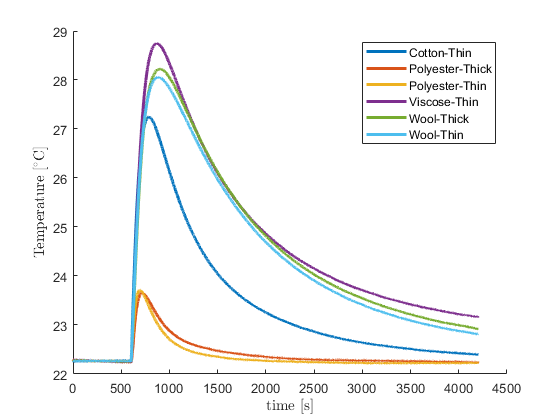

ISO_Material.Plot_Ave_Material_Temps